## Image presentation and analysis

## Part B: Sentinel imagery

There are many satellite products that can be used for your analysis. Sentinel 2 is one of the highest resolutions satellite datasest that are freely available to use without restrictions. The format of seninel imagery is slightly different than other products as teh imagery is stored as a ,jp2 file rather than a .tif file. This makes loading the data directly into MATLAB slightly more problematic and there are a number of steps that we need to do to convert the imagery to a .tif before it can be loaded. These steps are outlined in the supplementary file named `sentinel_preprocessing_notes.pdf.` For the purposes of this excercise we have downloaded jp2 files from the [Copernicus hub](https://scihub.copernicus.eu/dhus/#/home), which image Lake Naivasha, a freshwater lake in Kenya. These jp2 files have been converted to .tif files and are ready to be loaded directly into MATLAB.

When you access the Copernicus Hub to download imagery for yourself, you have the option of various Sentinel-2 products. The products are:

`S2MSI1C:` which represents the reflectance from the top-of-atmosphere 

`L2Ap`: Bottom-of-atmosphere reflectance in cartographic geometry (pilot products before March 2018)

`L2A`: Bottom-of-atmosphere reflectance in cartographic geometry i.e. with atmospheric correction applied

The major difference between the 1C products and the 2A products is that the 1C imagery may be affected by atmospheric conditions at the time of image acquisition, whereas the 2A product has attempted to account for and remove these artefacts. If we are happy with ESA to do these corrections for us, we can use the 2A product.

Similarly to Landsat, Sentinel 2 imagery also consists of several bands consisting of the reflectance information from different wavelengths. A description of these bands can be found [here](https://www.usgs.gov/centers/eros/science/usgs-eros-archive-sentinel-2?qt-science_center_objects=0#qt-science_center_objects). For our purposes, we are going to use band 4 (red), band 3 (green), band 2 (blue), and band 8 (near-infrared). Each of these bands have a pixel resolution of 10m. Let's begin by bringing the necessary files into MATLAB and extracting the various band information: 

dirIn_p1 = 'C:\_git_local\GEO8026_21_22\Block 05\data\kenya\'; % modify as required
dirIn_p2 = 'S2A_MSIL2A_20210607T073611_N0300_R092_T36MZE_20210607T101427.SAFE\GRANULE\L2A_T36MZE_A031120_20210607T075618\'; % this can stay the same
dirIn_p3 = 'IMG_DATA\R10m\';

% bring in the correct file
dirIn       = [dirIn_p1 dirIn_p2 dirIn_p3];
channels    = ['B04';'B03';'B02';'B08']; % r g b ir - this is the filenames
extension   = '.tif';

[B4,~]  = readgeoraster([dirIn, channels(1,:),extension]); % read georaster can read in geotiff files
[B3,~]  = readgeoraster([dirIn, channels(2,:),extension]); % read georaster can read in geotiff files
[B2,~]  = readgeoraster([dirIn, channels(3,:),extension]); % read georaster can read in geotiff files
[B8,R]  = readgeoraster([dirIn, channels(4,:),extension]); % read georaster can read in geotiff files
[x,y]   = pixcenters(R,abs(R.YIntrinsicLimits(2)-R.YIntrinsicLimits(1)),...
    abs(R.XIntrinsicLimits(2)-R.XIntrinsicLimits(1)));

Sometimes, GDAL fails to assign the correct coordinate reference system to the extracted .tif file. If this is the case then we will extract this from the metadata held within the .xml file. Otherwise, we can simply extract it from the variable `R:`

if isempty(R.ProjectedCRS) % if the projection output is empty i.e. not assigned
    metaDir     = [dirIn_p1 dirIn_p2];
    meta_file   = 'MTD_TL.xml';
    DOMnode     = readstruct([metaDir meta_file]);
    crs         = DOMnode.n1_Geometric_Info.Tile_Geocoding.HORIZONTAL_CS_NAME;  % this is the coordinate system
else
    crs         = R.ProjectedCRS.Name; % extract the coordinate system to the var names crs
end

Now that we have brought the imagery into MATLAB, we can take a look at it. Note that we apply a contrast adjustment to enhance its appearance:

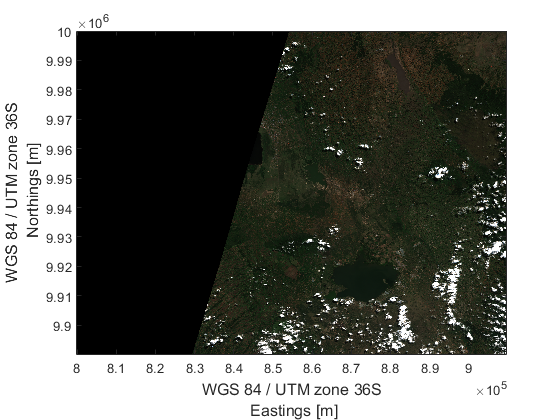

% RGB conversions for display purposes:
bands{1} = im2double(B4);   % Red channel
bands{2} = im2double(B3);   % Green channel
bands{3} = im2double(B2);   % Blue channel

bands{1} = imadjust(bands{1}, stretchlim(bands{1}));       % Adjustment on Red channel
bands{2} = imadjust(bands{2}, stretchlim(bands{2}));       % Adjustment on Green channel
bands{3} = imadjust(bands{3}, stretchlim(bands{3}));       % Adjustment on Blue channel

RGBImage = cat(3, bands{1}, bands{2}, bands{3});           % RGB image, datatype of double
RGBImage = uint8(rescale(RGBImage, 0, 255));               % Typecasted to uint8 and rescaled to 0-255 range for visualization

f0 = figure();
h0 = image(x,y,RGBImage); 
set(gca, 'YDir','normal'); % we need to ensure the y-axis is correct
hXlabel = xlabel([crs ' Eastings [m]']); % Create xlabel
hYlabel = ylabel([crs ' Northings [m]']); % Create ylabel
set([hXlabel, hYlabel]  , ...
    'FontSize',12);
axis tight
hold off

We can also begin to extract some characteristics about the landscape that we have imaged. Let's first calculate the [NDVI](https://earthobservatory.nasa.gov/features/MeasuringVegetation/measuring_vegetation_2.php) through the use of the Near Infrared (NIR) and red channels and plot the results:

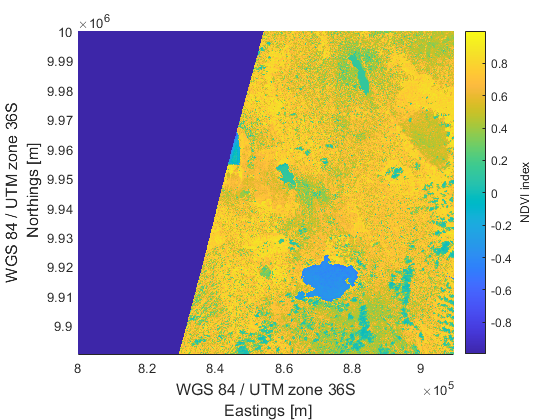

% find cells with no data within any of the channels - we will assign these as NaN later
idx         = find(B4 == 0 & B3 == 0 & B2 == 0 & B8 == 0 ); 

% Calculate the NDVI + plot the results
NDVI        = (single(B8) - single(B4))./ (single(B8) + single(B4));
NDVI(idx)	= NaN;

f1 = figure(); hold on
h1          = imagesc(x,y,NDVI); 
set(gca, 'YDir','normal'); % we need to ensure the y-axis is correct
c1          = colorbar;
ylabel(c1, 'NDVI index')
hXlabel = xlabel([crs ' Eastings [m]']); % Create xlabel
hYlabel = ylabel([crs ' Northings [m]']); % Create ylabel
set([hXlabel, hYlabel]  , ...
    'FontSize',12);
axis tight
hold off

Now let's calculate the [NDWI](https://custom-scripts.sentinel-hub.com/sentinel-2/ndwi/) through the use of the Near Infrared (NIR) and green channels and plot the results:

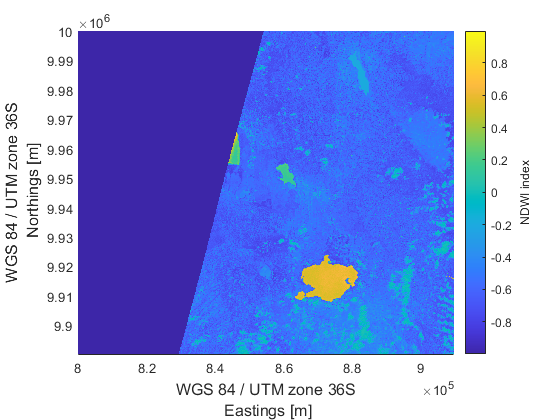

% Calculate the NDWI
NDWI    = (single(B3) - single(B8)) ./ (single(B3) + single(B8));
NDWI(idx) = NaN;
f2 = figure(); hold on
h2      = imagesc(x,y,NDWI);
set(gca, 'YDir','normal'); % we need to ensure the y-axis is correct
c2      = colorbar;
ylabel(c2, 'NDWI index');
hXlabel = xlabel([crs ' Eastings [m]']); % Create xlabel
hYlabel = ylabel([crs ' Northings [m]']); % Create ylabel
set([hXlabel, hYlabel]  , ...
    'FontSize',12);
axis tight
hold off